Santeri Saariokari 253345

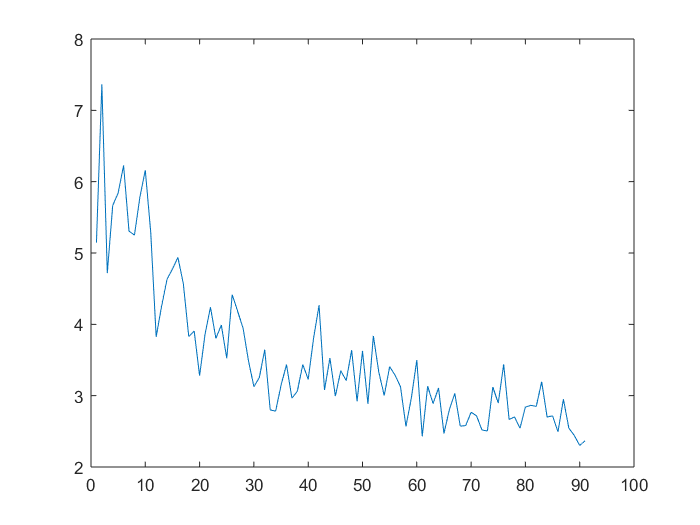

u = 2.^-52;
left = [];
right = [];

for n = 100:10:1000
    A = randi([-10 10], n);
    xe = ones(n,1);
    b = A.*xe;
    x = A\b;
    kappa = cond(A, 'inf');
    left = [left norm(round(x)-x)/norm(x)];
    right = [right u.*kappa];
end

plot(1:length(left),right./left)